decomp=CKCdecomp{2,2};
EMG=decomp.datafilt;

以MUPulse#30为例子

Pulses={};
Pulses{1}=decomp.MUPulses{30};
ctx=decomp.Ctx(:,30);
w1=decomp.W(:,21);
[sigcell]=sig2cell(EMG,4);
[muaparray,~]=muapExtraction(sigcell,Pulses,20,'STA');
tmpmuap=muaparray{1};
sig=[];
for i=1:12
    sig(i,:)=tmpmuap{i+1,1};
end
% sigcell{1,1}=NaN;
for i=1:13
    k=13-i;
    sig(k+13,:)=tmpmuap{i,2};
    sig(i+25,:)=tmpmuap{i,3};
    sig(k+39,:)=tmpmuap{i,4};
    sig(i+51,:)=tmpmuap{i,5};
end

放电串从cell格式转换为0-1序列

must=zeros(1,size(EMG,2));
must(Pulses{1})=1;

提取iEMG的Sipke Train

eaf_num=2

eaf_num = 2

eafdata = importdata(['Z:\Result\24-08-29iEMG-US-sEMG联合采集_程瑞佳\eaf\M2L1T' num2str(eaf_num) '.eaf']);
muNum = max(eafdata.data(:,2)); % MU的个数
iPulses = {};
must=zeros(muNum,size(EMG,2));
for mu = 1:muNum
    % iPulses就是这个eaf文件里分解得到的spike train，每个cell表示一个MU，里面的数字是该MU每次放电的时刻
    iPulses{mu} = round(eafdata.data(find(eafdata.data(:,2)==mu),1)'*2048);
    must(iPulses{mu})=1;
end

通过Least Squares的方法得到的muap

N=20;
exMUSTs = extend(must,N);

函数或变量 'must' 无法识别。

exMUSTs = exMUSTs(:,N/2+1:end-N/2+1)';%整段的muap
% exMUSTs = exMUSTs(:,N:end)';%MUAP前半段
% exMUSTs = exMUSTs(:,1:end-N+1)';%MUAP后半段
muaps = pinv(exMUSTs'*exMUSTs)*exMUSTs'*EMG(:,1:end)';% H混合矩阵??为什么是这里的muap是正的
figure;plot(muaps(:,1));title('LS得到的MUAP')
plot(sig(1,:));title('STA得到的MUAP')

对表面肌电extend，计算Cxx

exFactor=10;

eSig = extend(EMG,exFactor);

% eSig = eSig(:,exFactor/2:end-exFactor/2);%中心在中间
eSig = eSig(:,exFactor:end);%MUAP的后半段
CorrSig = eSig*eSig'/length(eSig);%??没有减去均值（白化）
invCorrSig = pinv(CorrSig);%%%Cxx-1

1) CKC方法计算

定义计算Csjx

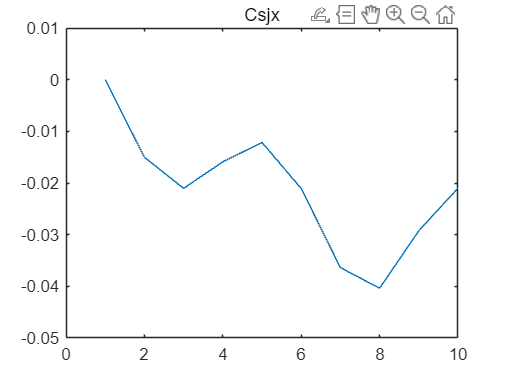

Csjx=eSig*must';
Csjx = Csjx/sqrt(sum(Csjx.^2));%归一化
figure;plot(Csjx(10:-1:1,1));title(['Csjx'])

通过LMMSE的公式的得到testIPT

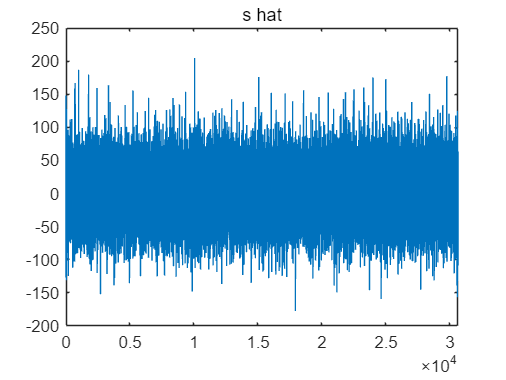

sbar=Csjx'*invCorrSig*eSig;
plot(sbar);title(["s hat"])

testIPT=sbar;

2）肌电混合模型计算

1  最小二乘法?L1约束的优化问题（效果差）

H=muaps';
s_est=pinv(H'*H)*H'*EMG;
figure;plot(s_est(1,:));
testIPT=s_est;

2.Weiner Deconvolution?

从PT中得到放电串

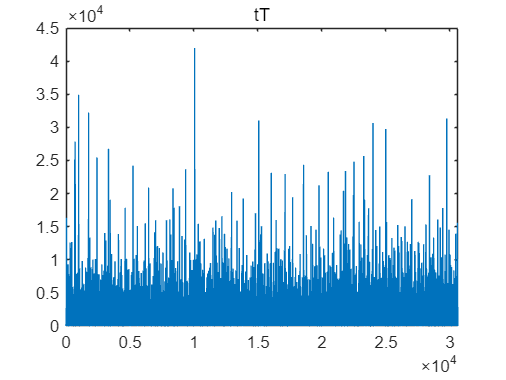

t_new = testIPT(1,:);
t_new([1:exFactor,end-exFactor+1:end]) = 0;
tT = abs(t_new).*t_new;
if  -min(t_new) > max(t_new)
    tT(find(t_new>0)) = 0;
else
    tT(find(t_new<0)) = 0;
end
tT = abs(tT); figure;plot(tT);title(['tT'])


edgepoint = 10*10;
fsamp=2048

fsamp = 2048

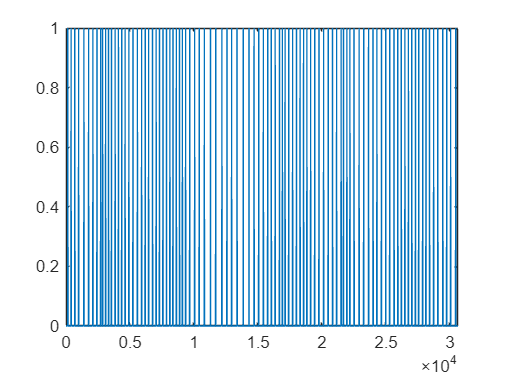

% [compInd,spikeSIL,C] = spikeExtraction(tT(edgepoint+1:end-edgepoint)',fsamp);
[compInd,spikeSIL,C] = spikeExtraction(tT',fsamp);
% compInd = compInd+exFactor;
compInd = remRepeatedInd(tT,compInd,round(fsamp/50));

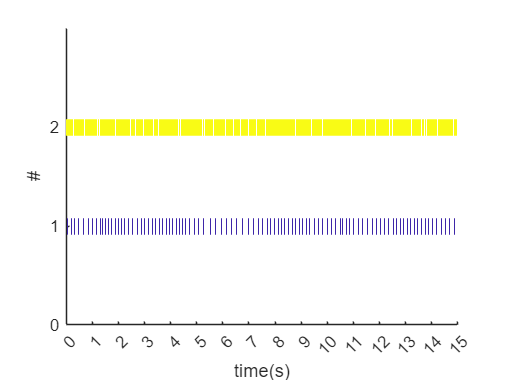

compare=iPulses;
compare{2}=compInd;
draw_PluseTime(compare,2048,1,100,0.5,1);

PulseMatch(compare(2),compare(1),0.3,2048)

ans = 1×10 table
    Pulses1    Pulses2    Sensitivity      RoA      Lag    Sensitivity_CC    FalseAlarm    Precision    Specificity      Acc  
    _______    _______    ___________    _______    ___    ______________    __________    _________    ___________    _______

       1          1         0.76531      0.16556     1        0.76531         0.93915       0.17442       0.98836      0.98764


tT与compInd、iEMG的pt绘图

iemgpt=iPulses{1};

idx=find(ismember(compInd,intersect(compInd,iemgpt)));
idx2=find(~ismember(compInd,intersect(compInd,iemgpt)));
idx4=find(~ismember(iemgpt,intersect(compInd,iemgpt)))

idx4 =      1     2     3     5     6     7    11    14    16    17    18    21    23    24    26    31    32    33    35    37    38    39    40    42    43    46    47    49    50    54    56    58    60    61    62    63    65    66    71    74    85    86    88    90    93    96    97


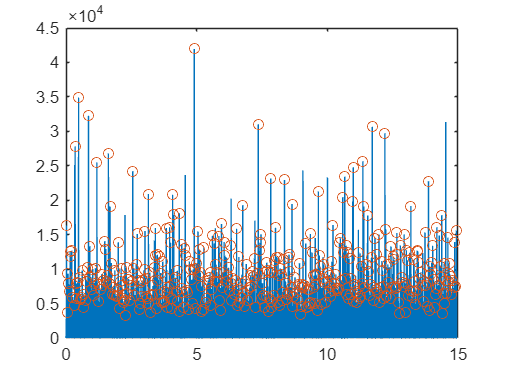

samespike=compInd(idx);
wrongspike=compInd(idx2);
missspike=iemgpt(idx4);
figure;
plot([1:length(tT)]/fsamp,tT,compInd/fsamp,tT(compInd),'o');

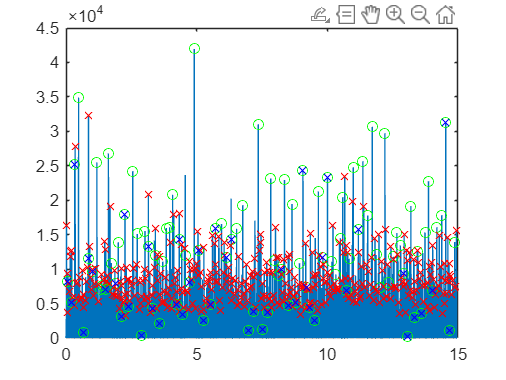

figure;
plot([1:length(tT)]/fsamp,tT,iemgpt/fsamp,tT(iemgpt),'go',wrongspike/fsamp,tT(wrongspike),'rx' ...
    ,missspike/fsamp,tT(missspike),'bx');

idx3=find(tT>1e4);
compare{3}=idx3

compare = 1×4 cell 数组
    {[139 398 685 986 1400 1766 2102 2421 2712 2864 3095 3325 3555 3841 4098 4356 4619 4914 5232 5581 5910 6191 6457 6763 7047 7306 7578 7855 8119 8360 8623 8872 9096 9349 9670 10055 10411 10813 11294 11704 12184 12581 12944 13369 13854 14303 14699 15064 15424 15765 16046 16349 16686 16912 17123 17408 17712 18014 18295 18568 18827 19120 19441 19774 20135 20496 20832 21149 21503 21684 21953 22190 22512 22909 23267 23648 23997 24299 24655 24992 25302 25637 25932 26207 26487 26763 27027 27315 27569 27879 28134 28412 28733 29060 29450 29755 30062 30461]}    {[43 101 156 208 267 326 388 453 534 631 717 809 857 914 986 1054 1120 1230 1275 1337 1396 1495 1613 1714 1765 1860 1948 2026 2098 2146 2218 2305 2421 2530 2583 2712 2806 2864 2968 3033 3119 3210 3263 3325 3405 3451 3555 3666 3721 3762 3832 3923 3998 4054 4098 4154 4234 4320 4363 4411 4490 4554 4615 4677 4728 4788 4848 4907 5014 5107 5155 5232 5311 5383 5493 5581 5700 5761 5802 5877 5930 6031 6135 6191 6263 6347 63

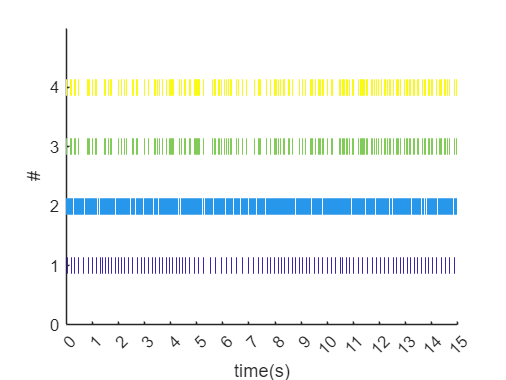

draw_PluseTime(compare,2048,1,100,0.5,1);figure;

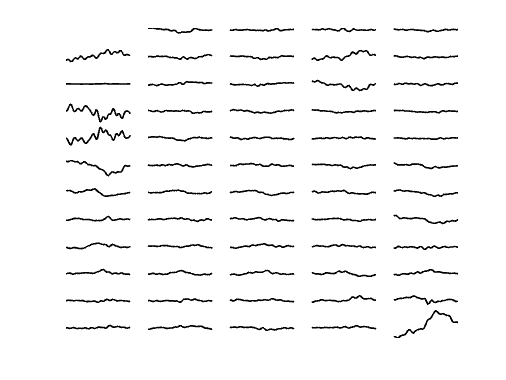

[sigcell]=sig2cell(EMG,4);
[muaparray,~]=muapExtraction(sigcell,compare,50,'STA');
figure;
plotArrayPotential(muaparray{3},,1);